# Workflow DES + Agua

**1. Importar los datos de viscosidad**

Visc_Eth=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Visc_Ethaline","VariableNamingRule","preserve")

Visc_Eth = 300×11 table
        DES          Set Type       Condition        Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Viscosity(Pa.s)    Viscosity(cP)        Reference         DES mole fraction
    ___________    ____________    ___________    _____________    __________________    ________________    ______________    _______________    _____________    __________________    _________________

    {'ChCl-EG'}    {'Computed'}    {'Mean'   }    {'DES+Water'}              0                    1              303.15             0.039               39         {'(Celebi, 2019)'}           NaN

Gráfica de datos de viscosidad

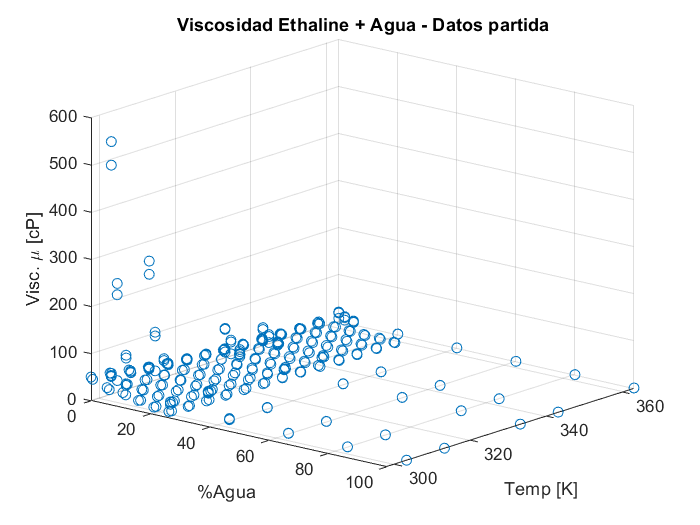

Masa_H2O_Eth=Visc_Eth.Mass_percent_Water*100;
Temp_Eth=Visc_Eth.("Temperature(K)");
Mu_Eth=Visc_Eth.("Viscosity(cP)");
figure, plot3(Masa_H2O_Eth,Temp_Eth,Mu_Eth,'o');
title('Viscosidad Ethaline + Agua - Datos partida'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Visc. \mu [cP]'),
view([40 20])

**2. División Conjuntos de Datos Entrenamiento y Prueba**

Matriz de datos de entrenamiento (2 predictores, 1 respuesta).

data1=[Masa_H2O_Eth,Temp_Eth,Mu_Eth];
n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 300
       NumTestSets: 1
         TrainSize: 240
          TestSize: 60

Datos de entrenamiento

idx_train=training(particion);
train_data_visc1=data1(idx_train,:)

train_data_visc1 =          0  303.1500   39.0000
         0  313.1500   30.0000
         0  333.1500   13.0000
         0  343.1500   10.8000
         0  363.1500    7.7000
         0  313.1500  257.0000
         0  333.1500   63.0000
         0  343.1500   39.0000
         0  363.1500   21.0000
         0  303.1500  486.0000



Masa_H2O_Eth_train=train_data_visc1(:,1);
Temp_Eth_train=train_data_visc1(:,2);
Mu_Eth_train=train_data_visc1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_visc1=data1(idx_test,:)

test_data_visc1 =          0  303.1500  536.0000
    2.0000  313.1500   27.0000
    2.0000  313.1500  101.0000
    2.0000  333.1500   37.0000
    5.0000  313.1500   57.0000
    5.0000  333.1500   21.0000
   20.0000  303.1500   12.0000
   20.0000  333.1500    4.8000
   20.0000  303.1500    7.0000
   20.0000  333.1500    3.4000



Masa_H2O_Eth_test=test_data_visc1(:,1);
Temp_Eth_test=test_data_visc1(:,2);
Mu_Eth_test=test_data_visc1(:,3);

**3. Regresión**

predictores_train=[Masa_H2O_Eth_train Temp_Eth_train];
regresion1 = fitlm(predictores_train,Mu_Eth_train)

regresion1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      230.71      43.074     5.3562    2.0094e-07
    x1             -0.46126    0.098858    -4.6658    5.1416e-06
    x2             -0.60707     0.13015    -4.6643    5.1758e-06


Number of observations: 240, Error degrees of freedom: 237
Root Mean Squared Error: 40.5
R-squared: 0.156,  Adjusted R-Squared: 0.149
F-statistic vs. constant model: 22, p-value = 1.74e-09

Ecuacion

coef1=table2array(regresion1.Coefficients(1,1));
coef2=table2array(regresion1.Coefficients(2,1));
coef3=table2array(regresion1.Coefficients(3,1));

fprintf('Ecuación')

Ecuación

fprintf('Viscosidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Viscosidad= 230.7119+(-0.4613)*%Agua+(-0.6071)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Eth_train),max(Masa_H2O_Eth_train))

Rango de porcentaje: 0.00 % - 100.00 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Eth_train),max(Temp_Eth_train))

Rango de temperatura: 297.79 K - 363.15 K